## Plotting


$$\begin{cases} f(x) = e^{-x} \sin(5x) \\ 0 \leq x \leq 5 \end{cases}$$


Using symbolic function.

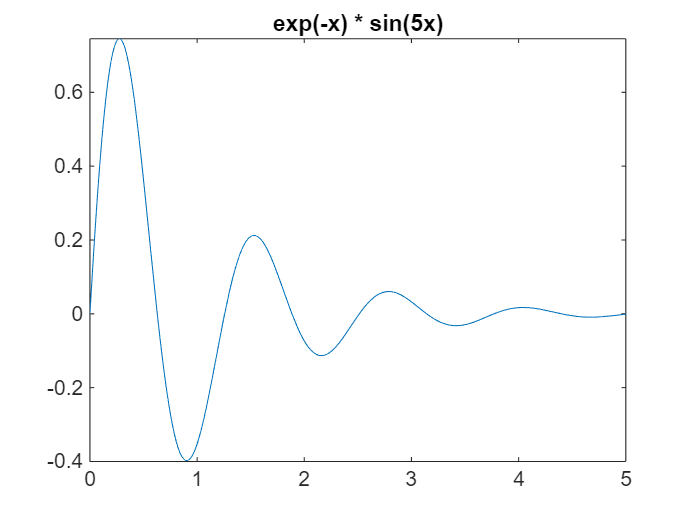

syms x
f = exp(-x) * sin(5 * x);
fplot(f, [0, 5]);
title('exp(-x) * sin(5x)')

Using range for `x`.

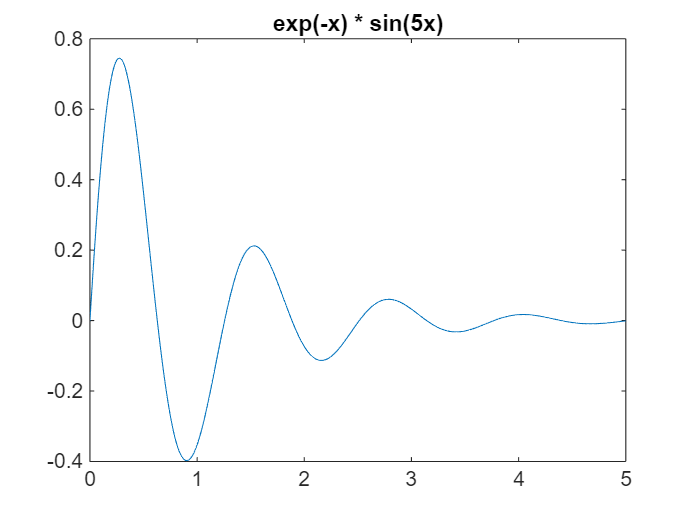

x = 0:0.01:5;
y = exp(-x) .* sin(5 .* x);
plot(x, y);
title('exp(-x) * sin(5x)');


$$\begin{cases} f(x, y) = \sin(x y) \\ -3 \leq x \leq 3 \\ -3 \leq y \leq 3 \end{cases}$$


Using symbolic function.

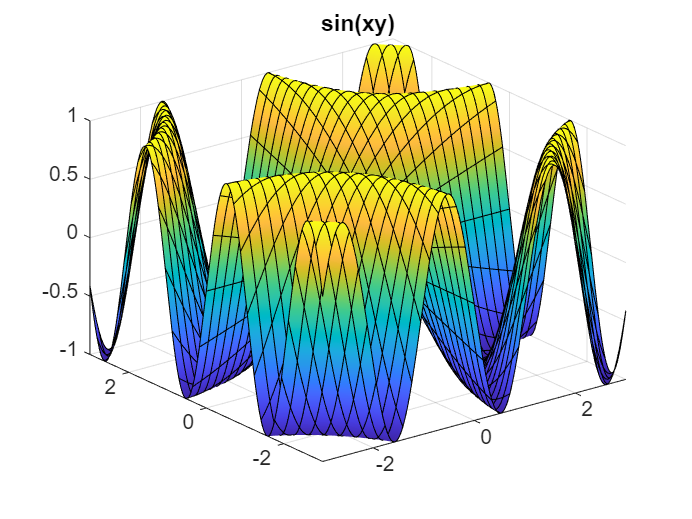

syms x y
f = sin(x * y);
fsurf(f, [-3, 3, -3, 3]);
title('sin(xy)');

Using range for `x` and `y`.

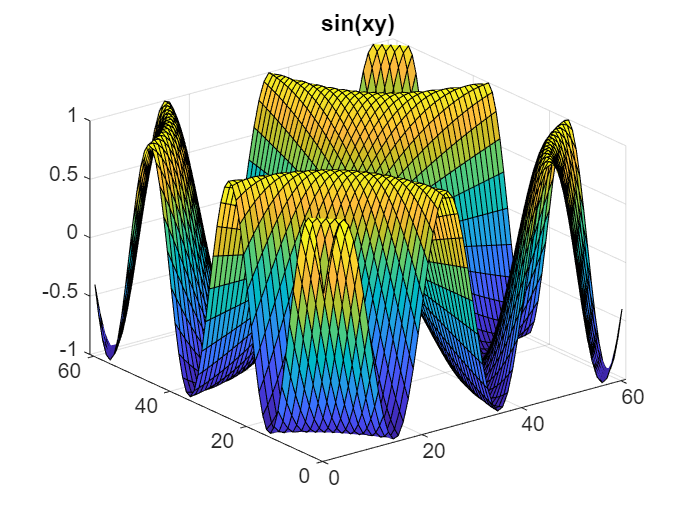

x = -3:0.1:3;
y = -3:0.1:3;
[x, y] = meshgrid(x, y);
z = sin(x .* y);
surf(z);
title('sin(xy)');

## Newton-Cotes Integration

By AI. :)

f = @(x) sin(x.^2);
a = 0;
b = 1;

n_values = [2, 4, 8, 12];

results_n = [];
results_integral = [];

for n_idx = 1:length(n_values)
    n = n_values(n_idx);
    num_points = n + 1;
    h = (b - a) / n;

    x_nodes = linspace(a, b, num_points);
    y_nodes = f(x_nodes);

    weights = zeros(1, num_points);
    syms s_sym;

    s_interpolation_nodes = 0:n;

    for k = 0:n
        Lk_s = 1;
        for j = 0:n
            if j ~= k
                Lk_s = Lk_s * (s_sym - s_interpolation_nodes(j+1)) / ...
                             (s_interpolation_nodes(k+1) - s_interpolation_nodes(j+1));
            end
        end
        
        weights(k+1) = double(int(Lk_s, s_sym, 0, n));
    end

    integral_approx = h * sum(weights .* y_nodes);
    
    results_n(end+1) = n;
    results_integral(end+1) = integral_approx;

    weights_str = sprintf('%6.4f ', weights);
    weights_str = strtrim(weights_str);
    
    fprintf('%-3d | %-5d | %-25s | %-20.10f\n', ...
            n, num_points, ['[' weights_str ']'], integral_approx);
end

2   | 3     | [0.3333 1.3333 0.3333]    | 0.3051811370        
4   | 5     | [0.3111 1.4222 0.5333 1.4222 0.3111] | 0.3102614237        
8   | 9     | [0.2791 1.6615 -0.2619 2.9618 -1.2811 2.9618 -0.2619 1.6615 0.2791] | 0.3102682888        
12  | 13    | [0.2597 1.8844 -1.4439 6.7980 -9.7981 16.6531 -16.7066 16.6531 -9.7981 6.7980 -1.4439 1.8844 0.2597] | 0.3102683017        


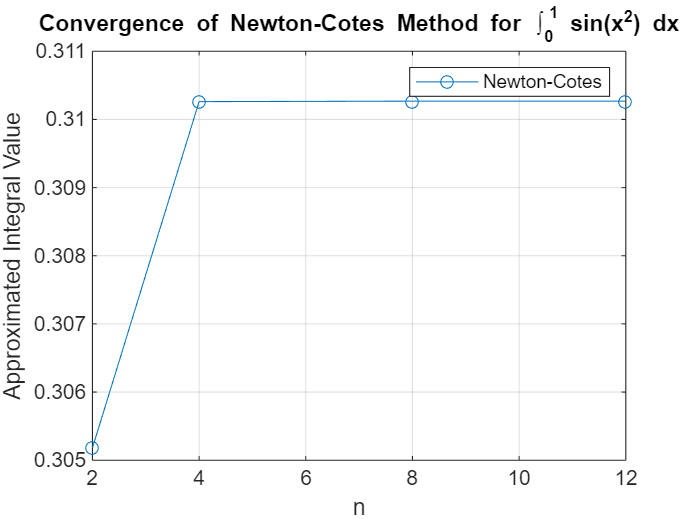


figure;
plot(results_n, results_integral, '-o', 'DisplayName', 'Newton-Cotes');
hold on;
xlabel('n');
ylabel('Approximated Integral Value');
title('Convergence of Newton-Cotes Method for \int_0^1 sin(x^2) dx');
legend show;
grid on;